GFDM parameters

Plot = true;

addpath(genpath('SEM'));

gfdm = struct;
gfdm.K = 8; % Subcarriers
gfdm.M = 7; % Subsymbols

gfdm.K_set = [7,0,1]; % Used subcarrier index(0 based)
gfdm.M_set = (1:6);              % Used subsymbol index(0 based). 1 guard subsymbol.

gfdm.CP = 0;    % CP length

Es = 1; % Symbol energy

% BW = 100; % Mhz

gfdm = GFDM_init(gfdm);

D = gfdm.D;
D_prime = gfdm.D_prime;

Normalized frequency $f$ and normalized frequency interval $\Delta f$

delta_f = 10^-2;     % Normalized frequency: f = F/B = F*Ts
f_range_end = 0.5;   % rc filter limit

% f_range_end should be divisible by delta_f
if mod(f_range_end,f_range_end)
    msg = 'normalized frequency sampling interval delta_f can not equally spaces f_range';
    error(msg);
end

f_range = [0 f_range_end];
f = -f_range(2):delta_f:f_range(2);


Interpolation filter $P(f)$

P = rc_filter(delta_f, f_range, 0.1);

Optimization problem & Dottorro iterative algorithm


$$\mathbf{S}=\mathbf{g}\mathbf{g}^H$$


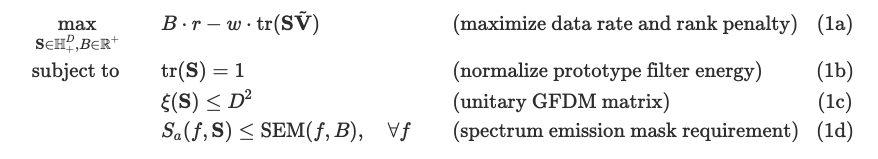

s_2 = 1;
w = 0.001;  % Rank 1 penalty
V_tilde = zeros(D);

counter = 1;
while abs(s_2) > 10^-6
    tic
    cvx_begin sdp %quiet
    variable S(D, D) hermitian nonnegative semidefinite
    variable B nonnegative
    expression psd_temp(length(P), 1)
    
    % SEM
    % mask = db2pow(ac(delta_f, f_range, 100));
    mask = dcp_SEM(delta_f, f_range, B);
    
    % PSD
    psd = (P.^2) .* PSD_S(S, f_range, psd_temp, gfdm.K, gfdm.M, gfdm.K_set, gfdm.M_set, gfdm.CP, delta_f, Es);
    
    minimize -B + w * trace(S * V_tilde) % (1a)
    subject to
    trace(S) == 1;                       % (1b)
    nep_S(S, gfdm.K, gfdm.M) <= D^2;     % (1c)
    psd <= mask;                         % (1d)
    
    cvx_end
    toc

 
Calling SDPT3 4.0: 6644 variables, 3243 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 3243
 dim. of sdp    var  = 336,   num. of sdp  blk  = 58
 dim. of linear var  = 203
 dim. of free   var  =  1 *** convert ublk to lblk
 number of dense column in A = 101
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.4e+02|1.0e+00|6.5e+05| 3.213223e+04  0.000000e+00| 0:0:00| spchol  1  1 
 1|0.282|0.023|9.7e+01|9.8e-01|7.0e+05| 3.126501e+04  2.803376e+00| 0:0:01| chol  1  1 
 2|0.143|0.194|8.4e+01|7.9e-0

Elapsed time is 56.681319 seconds.


$\tilde{\mathbf{V}}=\mathbf{U}\mathbf{U}^H, \mathbf{U} $ is $\mathbf{Q}$ with first column removed.

$\tilde{\mathbf{V}}$represents the (D-1)-dimensional space orthogonal to the principal eigenvector of $\mathbf{S}$ in the previous iteration.

    [U_svd, S_svd, ~] = svd(S);
    s_2 = S_svd(2, 2);
    fprintf('%d.s_2 = %f\n\n', counter, s_2);

1.s_2 = 0.000000



    U = U_svd(:, 2:end);
    V_tilde = U*U';
    
    counter = counter + 1;

Plot $S_a(f, \mathbf{S})$ and SEM

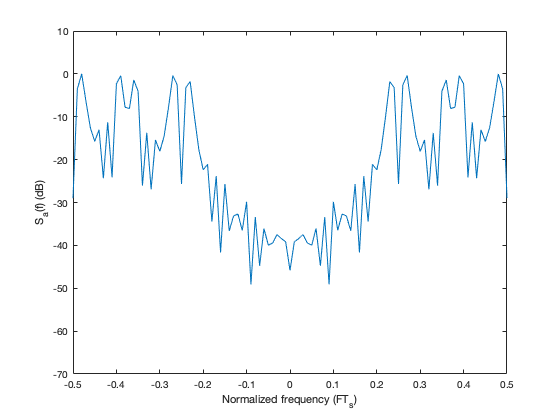

    if Plot == 1
        g = U_svd(:, 1) .* sqrt(S(1, 1));
        G = g2chaG(g, gfdm.K, gfdm.M);
        S_a = PSD(G, f_range, gfdm.K, gfdm.M, gfdm.K_set, gfdm.M_set, gfdm.CP, delta_f, Es);
        mask = max(mask, zeros(size(mask)));
        plot_PSD((P.^2) .* S_a, mask, f_range);
    end

end

Obtain the GFDM prototype filter $\mathbf{g}$

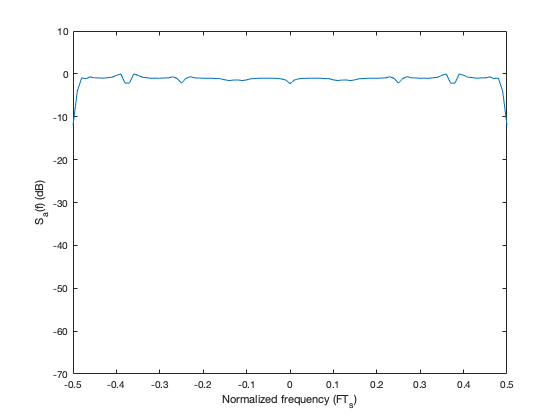

g = U_svd(:, 1) .* sqrt(S(1, 1));

psd_temp = zeros(size(P));
S_a = PSD_S(S, f_range, psd_temp, gfdm.K, gfdm.M, gfdm.K_set, gfdm.M_set, gfdm.CP, delta_f, Es);
plot_PSD((P.^2) .* S_a, mask, f_range);